# Estimation, Filtering and Detection

## Homework 2C: Asynchronous Sampling

## Timur Uzakov

## MACROS

clear all;

## Problem 1:

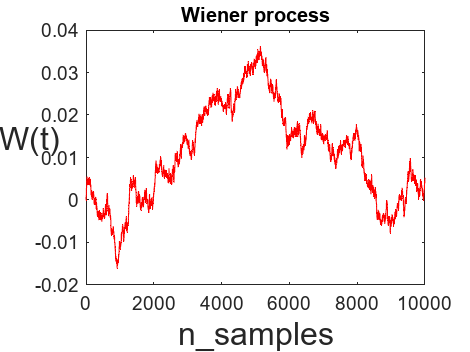

% Parameters
n_seconds = 1000;
Ts = 20;
sigma_e = 0.01;
sigma_process = 1;
tau = 50; % 50 seconds

% Continuous Wiener Process
dt = 0.1;

N = n_seconds/0.1;
dW = zeros(1,N);                
W = zeros(1,N);                 
dW(1) = 0.001*sqrt(dt)*randn();    
W(1) = dW(1);                  
for j = 2:N
    dW(j)= 0.001*sqrt(dt)*randn();
    W(j) = W(j-1) + dW(j);
end
f = gcf;

plot([1:1:n_seconds/dt],W,'r-')     
xlabel('n\_samples','FontSize',16)
ylabel('W(t)','FontSize',16,'Rotation',0)
title("Wiener process");
ind = 1;
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

ind = ind + 1;
W_continuous = W;
% mean and variance

% Wiener Process (discrete signal)
dt = Ts;
W_discrete = zeros(1,n_seconds/Ts); 
N = n_seconds/Ts;         
for j = 1:n_seconds/Ts
    W_discrete(j) = W(j*Ts/0.1);
end

% Continuous-time system
% . 
% x = Ax + Bu + Gd  + w      {State equation}
% y = Cx + Du + 0*d + v      {Measurements}

[A,B,C,D] = tf2ss(1,[tau^2 2*tau 1]);
G = [1;0];
B = [B G];
D = [D 0];
sys = ss(A,B,C,D);
u_continuous = ones(1,n_seconds/0.1);
continuous_signal_y = lsim(sys,[u_continuous;W_continuous],[0.1:0.1:n_seconds]) + sigma_e*randn;

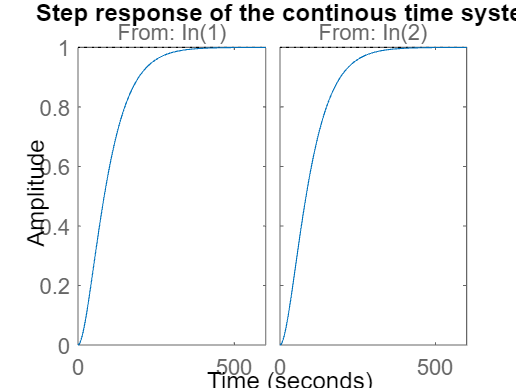

f = gcf;
step(sys);
title("Step response of the continous time system");
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

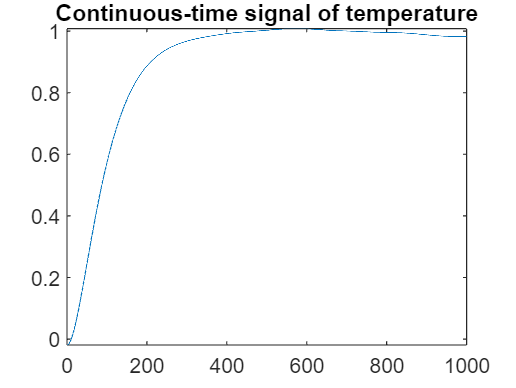

ind = ind + 1;
f = gcf;
plot([0.1:0.1:n_seconds],continuous_signal_y);
title("Continuous-time signal of temperature");
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

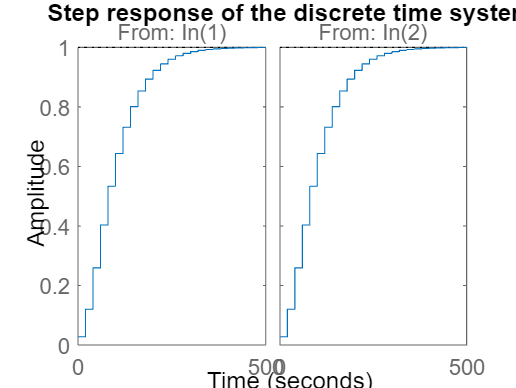

ind = ind +1;
% Discrete-time system
dsys = c2d(sys,Ts,'tustin');
f = gcf;
step(dsys);
title("Step response of the discrete time system");
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

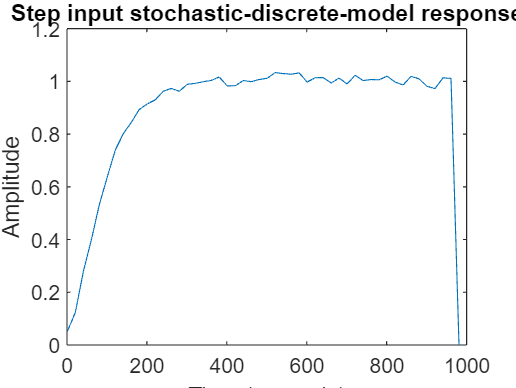

ind = ind + 1;
Ad = dsys.A;
Bd = dsys.B;
Cd = dsys.C;
Dd = dsys.D;
disturbance = W_discrete;

x = zeros(2,n_seconds/Ts);
y = zeros(1,n_seconds/Ts);
u = ones(1,n_seconds/Ts);

for i=1:(n_seconds/Ts-1)
    x(:,i+1) = Ad*x(:,i) + Bd*[u(i);disturbance(i)] + sigma_process.*randn(2,1);
    y(:,i)   = Cd*x(:,i) + Dd*[u(i);disturbance(i)] + sigma_e*randn(1,1);
end
f = gcf;
plot([1:20:n_seconds], y)
ylabel("Amplitude");
xlabel("Time (seconds)");
title("Step input stochastic-discrete-model response");
exportgraphics(f,'fig5.png','Resolution',1000);

## Problem 2:

% Synchronous sampling
Tc = Ts;
etta = (Ts-Tc)/Ts;
Rc = sigma_e^2;
Qc = [sigma_process^2 sigma_process^2;sigma_process^2 sigma_process^2];

A11 = A(1,1);
A12 = A(1,2);
A21 = A(2,1);
A22 = A(2,2);

A_sync = expm(A*Ts);
B_int = [(exp(A11*Ts)-exp(A11*0))/A11 (exp(A12*Ts)-exp(A12*0))/A12;(exp(A21*Ts)-exp(0))/A21 Ts];
B_sync = B_int*B;
C_sync = C*expm(A*etta*Ts);

%% The following method leads to Qyy = 10^15
% 
% 
% C11 = C(1,1);
% C12 = C(1,2);
% 
% Q11 = Qc(1,1);
% Q12 = Qc(1,2);
% Q21 = Qc(2,1);
% Q22 = Qc(2,2);
%funQ = @(x) expm(A*x)*Qc*expm(A'*x);
% syms C11 C12 x A11 A12 A21 A22 Q11 Q12 Q21 Q22
% [exp(A11*x) exp(A12*x); exp(A21*x) exp(A22*x)]*[Q11 Q12; Q21 Q22]
% result 
% [Q11*exp(A11*x) + Q21*exp(A12*x), Q12*exp(A11*x) + Q22*exp(A12*x);Q11*exp(A21*x) + Q21*exp(A22*x), Q12*exp(A21*x) + Q22*exp(A22*x)]
% * [exp(A11*x) exp(A21*x); exp(A12*x) exp(A22*x)]
% result
% [exp(A11*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A12*x)*(Q12*exp(A11*x) + Q22*exp(A12*x)), exp(A21*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A22*x)*(Q12*exp(A11*x) + Q22*exp(A12*x))]
% [exp(A11*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A12*x)*(Q12*exp(A21*x) + Q22*exp(A22*x)), exp(A21*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A22*x)*(Q12*exp(A21*x) + Q22*exp(A22*x))]
% expansion

% [Q11*exp(2*A11*x) + Q22*exp(2*A12*x) + Q12*exp(A11*x)*exp(A12*x) +
% Q21*exp(A11*x)*exp(A12*x), 
% Q11*exp(A11*x)*exp(A21*x) + Q12*exp(A11*x)*exp(A22*x) +
% Q21*exp(A12*x)*exp(A21*x) + Q22*exp(A12*x)*exp(A22*x)]



% [Q11*exp(A11*x)*exp(A21*x) + Q12*exp(A12*x)*exp(A21*x) +
% Q21*exp(A11*x)*exp(A22*x) + Q22*exp(A12*x)*exp(A22*x),
% Q11*exp(2*A21*x) + Q22*exp(2*A22*x) + Q12*exp(A21*x)*exp(A22*x) + 
% Q21*exp(A21*x)*exp(A22*x)]
% 
% funQ111 = @(z) Q11*exp(2*A11*z) ;
% funQ112 = @(z) Q22*exp(2*A12*z)
% funQ113 = @(z) Q12*exp((A11+A12)*z);
% funQ114 = @(z) Q21*exp((A11+A12)*z);
% 
% funQ121 = @(z) Q11*exp((A11+A21)*z);
% funQ122 = @(z) Q12*exp((A11+A22)*z);
% funQ123 = @(z) Q21*exp((A12+A21)*z);
% funQ124 = @(z) Q22*exp((A12+A22)*z);
% 
% funQ211 = @(z) Q11*exp((A11+A21)*z);
% funQ212 = @(z) Q12*exp((A12+A21)*z);
% funQ213 = @(z) Q21*exp((A11+A22)*z);
% funQ214 = @(z) Q22*exp((A12+A22)*z);
% 
% funQ221 = @(z)  Q11*exp(2*A21*z);
% funQ222 = @(z)  Q22*exp(2*A22*z);
% funQ223 = @(z)  Q12*exp((A21+A22)*z);
% funQ224 = @(z)  Q21*exp((A21+A22)*z);
% 
% Q_int_111 = integral(funQ111,0,Ts);
% Q_int_112 = integral(funQ112,0,Ts);
% Q_int_113 = integral(funQ113,0,Ts);
% Q_int_114 = integral(funQ114,0,Ts);
% 
% Q_int_121 = integral(funQ121,0,Ts);
% Q_int_122 = integral(funQ122,0,Ts);
% Q_int_123 = integral(funQ123,0,Ts);
% Q_int_124 = integral(funQ124,0,Ts);
% 
% Q_int_211 = integral(funQ211,0,Ts);
% Q_int_212 = integral(funQ212,0,Ts);
% Q_int_213 = integral(funQ213,0,Ts);
% Q_int_214 = integral(funQ214,0,Ts);
% 
% Q_int_221 = integral(funQ221,0,Ts); %!
% Q_int_222 = integral(funQ222,0,Ts);
% Q_int_223 = integral(funQ223,0,Ts); %!
% Q_int_224 = integral(funQ224,0,Ts); %!
% 
% Qint11 = Q_int_111 + Q_int_112 + Q_int_113 + Q_int_114;
% Qint12 = Q_int_121 + Q_int_122 + Q_int_123 + Q_int_124;
% Qint21 = Q_int_211 + Q_int_212 + Q_int_213 + Q_int_214;
% Qint22 = Q_int_221 + Q_int_222 + Q_int_223 + Q_int_224;
% 
% Q_sync = [Qint11 Qint12;Qint21 Qint22];

% Estimation of R_sync
% syms C11 C12 x A11 A12 A21 A22 Q11 Q12 Q21 Q22
% [C11 C12]*[exp(A11*x) exp(A12*x); exp(A21*x) exp(A22*x)]
% % result : [C11*exp(A11*x) + C12*exp(A21*x), C11*exp(A12*x) + C12*exp(A22*x)]
% [C11*exp(A11*x) + C12*exp(A21*x), C11*exp(A12*x) + C12*exp(A22*x)]*[Q11 Q12; Q21 Q22]
% % result : [Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x)), Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x))]
% [Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x)), Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x))]*[exp(A11*x) exp(A21*x); exp(A12*x) exp(A22*x)]
% % result : [exp(A11*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A12*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x))), exp(A21*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A22*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x)))]
% [exp(A11*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A12*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x))), exp(A21*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A22*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x)))]*[C11; C12]
% % result : C11*(exp(A11*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A12*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x)))) + C12*(exp(A21*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A22*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x))))
% expand(C11*(exp(A11*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A12*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x)))) + C12*(exp(A21*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A22*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x)))))
% % result : C11^2*Q11*exp(2*A11*x) + C12^2*Q11*exp(2*A21*x) + C11^2*Q22*exp(2*A12*x) + C12^2*Q22*exp(2*A22*x) + C11^2*Q12*exp(A11*x)*exp(A12*x) + C11^2*Q21*exp(A11*x)*exp(A12*x) + C12^2*Q12*exp(A21*x)*exp(A22*x) + C12^2*Q21*exp(A21*x)*exp(A22*x) + 2*C11*C12*Q11*exp(A11*x)*exp(A21*x) + C11*C12*Q12*exp(A11*x)*exp(A22*x) + C11*C12*Q12*exp(A12*x)*exp(A21*x) + C11*C12*Q21*exp(A11*x)*exp(A22*x) + C11*C12*Q21*exp(A12*x)*exp(A21*x) + 2*C11*C12*Q22*exp(A12*x)*exp(A22*x)
% funR1 = @(p) C11^2*Q11*exp(2*A11*p);
% funR2 = @(p) C12^2*Q11*exp(2*A21*p);
% funR3 = @(p) C11^2*Q22*exp(2*A12*p);
% funR4 = @(p)  C12^2*Q22*exp(2*A22*p);
% funR5 = @(p)  C11^2*Q12*exp((A11+A12)*p);
% funR6 = @(p)  C11^2*Q21*exp((A11+A12)*p);
% funR7 = @(p)  C12^2*Q12*exp((A21+A22)*p);
% funR8 = @(p)  C12^2*Q21*exp((A21+A22)*p);
% funR9 = @(p) 2*C11*C12*Q11*exp((A11+A21)*p);
% funR10 = @(p)  C11*C12*Q12*exp((A11+A22)*p);
% funR11 = @(p)  C11*C12*Q12*exp((A12+A21)*p);
% funR12 = @(p)   C11*C12*Q21*exp((A11+A22)*p);
% funR13 = @(p)  C11*C12*Q21*exp((A12+A21)*p);
% funR14 = @(p) 2*C11*C12*Q22*exp((A12+A22)*p);
% 
% R_int_1 = integral(funR1,0,etta*Ts);
% R_int_2 = integral(funR2,0,etta*Ts);
% R_int_3 = integral(funR3,0,etta*Ts);
% R_int_4 = integral(funR4,0,etta*Ts);
% R_int_5 = integral(funR5,0,etta*Ts);
% R_int_6 = integral(funR6,0,etta*Ts);
% R_int_7 = integral(funR7,0,etta*Ts);
% R_int_8 = integral(funR8,0,etta*Ts);
% R_int_9 = integral(funR9,0,etta*Ts);
% R_int_10 = integral(funR10,0,etta*Ts);
% R_int_11 = integral(funR11,0,etta*Ts);
% R_int_12 = integral(funR12,0,etta*Ts);
% R_int_13 = integral(funR13,0,etta*Ts);
% R_int_14 = integral(funR14,0,etta*Ts);
% R_int = R_int_1 + R_int_2 + R_int_3 + R_int_4 + R_int_5 + R_int_6 + R_int_7 + R_int_8 + R_int_9 + R_int_10 + R_int_11 + R_int_12 + R_int_13 + R_int_14; 
% R_sync = R_int + Rc;
% disp(R_sync)


% Method 2
funQ = @(x) expm(A*x)*Qc*expm(A'*x);
Q_sync = integral(funQ,0,Ts,'ArrayValued', true);


funR = @(x) C*expm(A*x)*Qc*expm(A'*x)*C';
R_int = integral(funR,0,etta*Ts,'ArrayValued',1);
R_sync = R_int + Rc;


funS = @(x) expm(A*x)*Qc*expm(A'*x)*C';
S_sync = integral(funS,0,etta*Ts,'ArrayValued', true);

P_pred = [1 10;10 300];

xhat = zeros(2, N);

P_pred_eig = zeros(2, N);
P_pred_eig(:,1) = eig(P_pred);

P_corr_eig = zeros(2, N);

y_hat = zeros(1,n_seconds/Ts);

for i = 1:N-1
    % Filtering
    % Correction step
    % innovation
    r = y(:,i) - C_sync*xhat(:, i);
    % residual covariance
    S = C_sync*P_pred*C_sync' + R_sync;
    % Kalman gain
    W = P_pred*C_sync'/S;
    % update
    xhat(:, i) = xhat(:, i) + W*r; 
    P_corr = P_pred - W*C_sync*P_pred;
    % P(t|t)
    P_corr_eig(:,i) = eig(P_corr);

    % Prediction step
    xhat(:, i+1) = A_sync*xhat(:,i); + B_sync*u(:,i);
    P_pred = A_sync*P_corr*A_sync' + Q_sync;
    % P(t+1|t)
    P_pred_eig(:,i+1) = eig(P_pred);
end
P_sync_pred = P_pred

P_sync_pred = 1.0e+03 *

    0.0104    0.1387
    0.1387    3.8640


P_sync_corr = P_corr

P_sync_corr =     6.1471   19.3147
   19.3147  537.9818


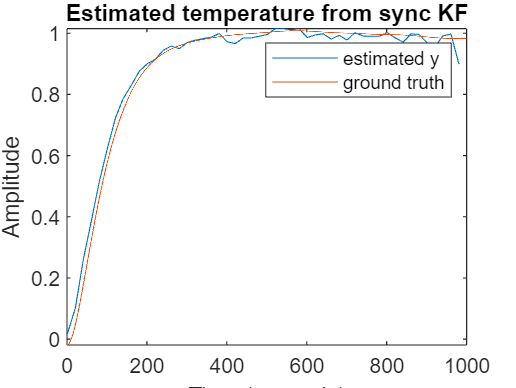


f = gcf;
plot([1:20:n_seconds], C_sync*xhat)
hold on
plot([0.1:0.1:n_seconds], continuous_signal_y);
hold off
ylabel("Amplitude");
xlabel("Time (seconds)");
title("Estimated temperature from sync KF");
legend("estimated y", "ground truth");
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

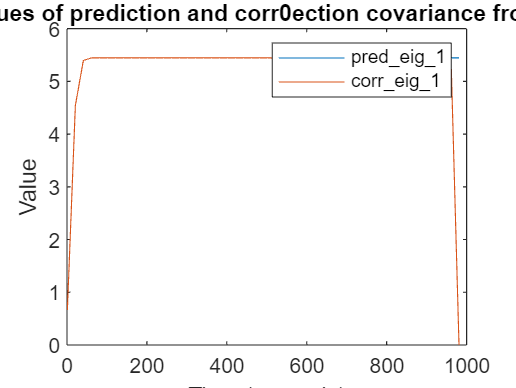

ind = ind + 1;
f = gcf;
plot([1:20:n_seconds], P_pred_eig(1,:));
hold on 
plot([1:20:n_seconds], P_corr_eig(1,:));
hold off
ylabel("Value");
xlabel("Time (seconds)");
legend("pred\_eig\_1","corr\_eig\_1");
title("Eigen values of prediction and corr0ection covariance from sync KF");
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

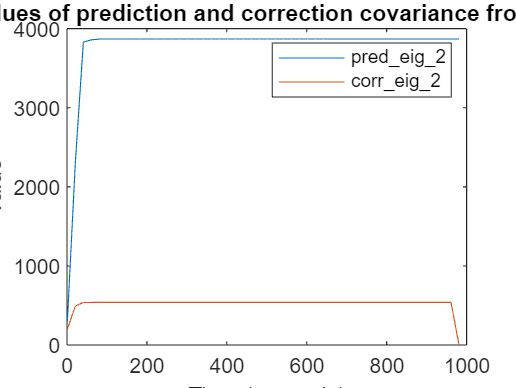

ind = ind + 1;
f = gcf;
plot([1:20:n_seconds], P_pred_eig(2,:));
hold on
plot([1:20:n_seconds], P_corr_eig(2,:));
hold off
ylabel("Value");
xlabel("Time (seconds)");
legend("pred\_eig\_2","corr\_eig\_2");
title("Eigen values of prediction and correction covariance from sync KF");
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

ind = ind +1;

## Problem 3:

Tc


    10



Prediciton values


   1.0e+03 *

    0.0102    0.1198
    0.1198    2.9952



Correction values


    3.9258   -2.0633
   -2.0633  615.5963



Tc


     1



Prediciton values


   1.0e+03 *

    0.0102    0.1191
    0.1191    3.5655



Correction values


   1.0e+03 *

    0.0042   -0.0008
   -0.0008    1.1636



Tc


    0.1000



Prediciton values


   1.0e+03 *

    0.0102    0.1193
    0.1193    3.6536



Correction values


   1.0e+03 *

    0.0043   -0.0004
   -0.0004    1.2370



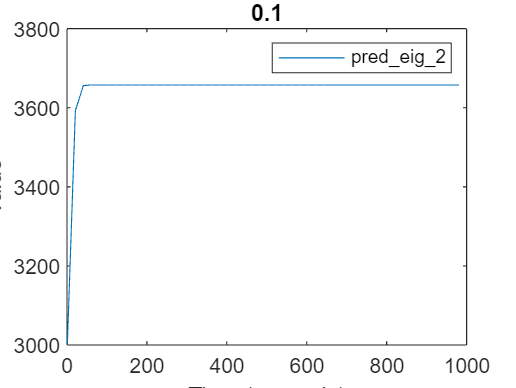

% Asynchrounous sampling with a set of 3 Kalman filter models
Tcs = [100 10 1]; % time in samples, because 0.1 cannot be represented in samples of Wiener process
yhat_10 = zeros(2, N);
yhat_1 = zeros(2, N);
yhat_01 = zeros(2, N);
Rc = sigma_e^2;
Qc = [sigma_process^2 sigma_process^2;sigma_process^2 sigma_process^2];

MSE = zeros(1, 3);
for j = 1:3
    Tc = Tcs(j);
    etta = (Ts-Tc*0.1)/Ts;

    %% Measuring at different points 
    y_meas = zeros(1,n_seconds/Ts);
    for i=2:n_seconds/Ts
        y_meas(i-1) = continuous_signal_y(i*Ts*10-Tc); % this is why Tcs is multiplied by 10 times
    end

    funD = @(x) expm(A*x);
    funS = @(x) expm(A*x)*Qc*expm(A'*x)*C';
    funQ = @(x) expm(A*x)*Qc*expm(A'*x);

    A_async = expm(A*Ts);
    S_async = integral(funS,0,etta*Ts,'ArrayValued', true);
    D_async = integral(funD,0,etta*Ts,'ArrayValued', true);
    B_int = [(exp(A11*Ts)-exp(A11*0))/A11 (exp(A12*Ts)-exp(A12*0))/A12;(exp(A21*Ts)-exp(0))/A21 Ts];
    B_async = B_int*B;
    C_async = C*expm(A*etta*Ts);
    Q_async = integral(funQ,0,Ts,'ArrayValued', true);
    
    
    funR = @(x) C*expm(A*x)*Qc*expm(A'*x)*C';
    R_int = integral(funR,0,etta*Ts,'ArrayValued',1);
    R_async = R_int + Rc;
    
    xhat = zeros(2, N);
    P_pred_eig = zeros(2, N);
    P_pred = [10 100;100 3000];
    y_hat = zeros(1,n_seconds/Ts);
    
    P_pred_eig(:,1) = eig(P_pred);
    for i = 1:N-1
        % Filtering
        % Correction step
        % innovation
        r = y_meas(:,i) - C_async*xhat(:, i);
        % residual covariance
        S = C_async*P_pred*C_async' + R_async;
        % Kalman gain
        W = P_pred*C_async'/S;
        % update
        xhat(:, i) = xhat(:, i) + W*r; 
        P_corr = P_pred - W*C_async*P_pred;
        % P(t|t)
        P_corr_eig(:,i) = eig(P_corr);
    
        % Prediction step
        xhat(:, i+1) = A_async*xhat(:,i); + B_async*u(:,i);
        P_pred = A_async*P_corr*A_async' + Q_async;
        % P(t+1|t)
        P_pred_eig(:,i+1) = eig(P_pred);
    end
    if (j == 1)
        yhat_10 = C_async*xhat;
        P_pred_10 = P_pred;
        P_corr_10 = P_corr;
    end
    if (j == 2)
        yhat_1 = C_async*xhat;
        P_pred_1 = P_pred;
        P_corr_1 = P_corr;
    end
    if (j == 3)
        yhat_01 = C_async*xhat;
        P_pred_01 = P_pred;
        P_corr_01 = P_corr;
    end
    
    f = gcf;
    plot([1:20:n_seconds], C_async*xhat)
    ylim([0.9 1.2])
    hold on
    plot([0.1:0.1:n_seconds], continuous_signal_y);
    hold off
    ylabel("Amplitude");
    xlabel("Time (seconds)");
    legend("estimated y", "ground truth");
    title(["Estimated temperature from async KF Tc:" num2str(Tc*0.1)]);
    exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
    ind = ind+1;
    disp("Tc")
    disp(Tc*0.1)
    disp("Prediciton values")
    disp(P_pred)
    disp("Correction values")
    disp(P_corr)
   
    
    f = gcf;
    plot([1:20:n_seconds], P_pred_eig(1,:));
    ylabel("Value");
    xlabel("Time (seconds)");
    legend("pred\_eig\_1");
    title(["Eigen value of prediction covariance from async KF  Tc:" num2str(Tc*0.1)]);
    exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
    ind = ind+1;
    f = gcf;
    plot([1:20:n_seconds], P_pred_eig(2,:));
    ylabel("Value");
    xlabel("Time (seconds)");
    legend("pred\_eig\_2");
    title(["Eigen value of prediction covariance async KF  Tc:" num2str(Tc*0.1)]);
    exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
    ind = ind+1;
    MSE(j) = calculateMSE(C_async*xhat,y_meas);
end

## Problem 4.1:

% Show impact of neglecting S in case of asynchronous sampling - method 1
Tcs = [100 10 1];
Tc = Tcs(3);
etta = (Ts-Tc*0.1)/Ts;
Qc = [sigma_process^2 0;0 sigma_process^2];

A_async = expm(A*Ts);
B_int = [(exp(A11*Ts)-exp(A11*0))/A11 (exp(A12*Ts)-exp(A12*0))/A12;(exp(A21*Ts)-exp(0))/A21 Ts];
B_async = B_int*B;
C_async = C*expm(A*etta*Ts);

funQ = @(x) expm(A*x)*Qc*expm(A'*x);
Q_async = integral(funQ,0,Ts,'ArrayValued', true);


funR = @(x) C*expm(A*x)*Qc*expm(A'*x)*C';
R_int = integral(funR,0,etta*Ts,'ArrayValued',1);
R_async = R_int + Rc;

%% Measuring at different points 
y_meas = zeros(1,n_seconds/Ts);
for i=2:n_seconds/Ts
    y_meas(i-1) = continuous_signal_y(i*Ts*10-Tc);
end

xhat = zeros(2, N);
P_pred_eig = zeros(2, N);
P_pred = [1 0;0 300];
y_hat = zeros(1,n_seconds/Ts);

P_pred_eig(:,1) = eig(P_pred);
for i = 1:N-1
    % Filtering
    % Correction step
    % innovation
    
    r = y_meas(:,i) - C_async*xhat(:, i);
    % residual covariance
    S = C_async*P_pred*C_async' + R_async;
    % Kalman gain
    W = P_pred*C_async'/S;
    % update
    xhat(:, i) = xhat(:, i) + W*r; 
    P_corr = P_pred - W*C_async*P_pred;
    P_corr(1,2) = 0;
    P_corr(2,1) = 0;
    % P(t|t)
    P_corr_eig(:,i) = eig(P_corr);
    

    % Prediction step
    xhat(:, i+1) = A_async*xhat(:,i); + B_async*u(:,i);
    P_pred = A_async*P_corr*A_async' + Q_async;
    % P(t+1|t)
    P_pred(1,2) = 0;
    P_pred(2,1) = 0;
    P_pred_eig(:,i+1) = eig(P_pred);
end
disp("Prediciton values without S")

Prediciton values without S


disp(P_pred)

   1.0e+03 *

    0.0110         0
         0    5.1845



disp("Correction values without S")

Correction values without S


disp(P_corr)

   1.0e+03 *

    0.0085         0
         0    2.4445



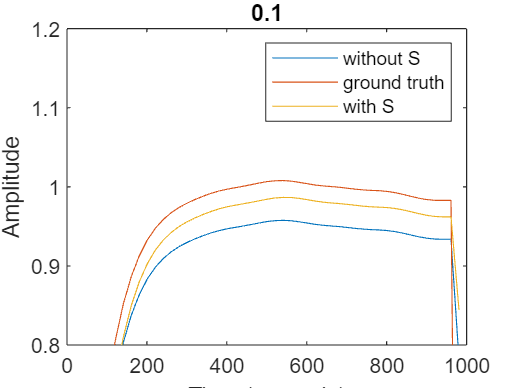


f = gcf;
plot([1:20:n_seconds], C_async*xhat);
hold on
plot([1:20:n_seconds], y_meas);
plot([1:20:n_seconds], yhat_10);
hold off
%ylim([0.9 1.2])
ylabel("Amplitude");
xlabel("Time (seconds)");
ylim([0.8 1.2]);
legend("without S", "ground truth","with S")
title(["Estimated temperature from async KF with neglected S Tc:" num2str(Tc*0.1)]);
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

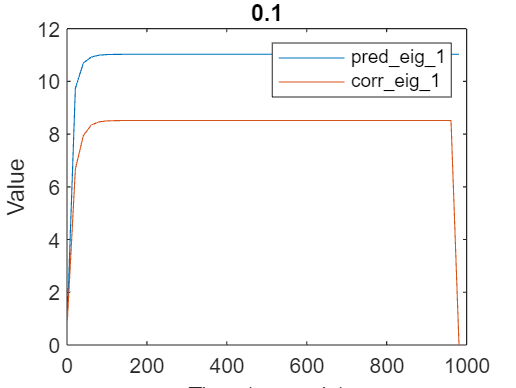

ind = ind + 1;
f = gcf;
plot([1:20:n_seconds], P_pred_eig(1,:));
hold on 
plot([1:20:n_seconds], P_corr_eig(1,:));
hold off
ylabel("Value");
xlabel("Time (seconds)");
legend("pred\_eig\_1","corr\_eig\_1");
title(["Eigen values of prediction and correction covariance from async KF  Tc:" num2str(Tc*0.1)]);
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

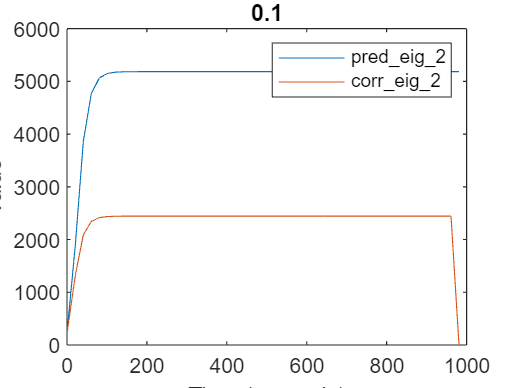

ind = ind + 1;
f = gcf;
plot([1:20:n_seconds], P_pred_eig(2,:));
hold on 
plot([1:20:n_seconds], P_corr_eig(2,:));
hold off
ylabel("Value");
xlabel("Time (seconds)");
legend("pred\_eig\_2","corr\_eig\_2");
title(["Eigen values of prediction and correction covariance from async KF  Tc:" num2str(Tc*0.1)]);
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

ind = ind + 1;
disp("MSE");

MSE


disp(calculateMSE(C_async*xhat,y_meas));

    0.1232



## Problem 4.2:

% Show impact of neglecting S in case of asynchronous sampling - method 2
Tcs = [100 10 1];
Tc = Tcs(3)*0.1;
etta = (Ts-Tc)/Ts;

A_async = expm(A*Ts);
B_int = [(exp(A11*Ts)-exp(A11*0))/A11 (exp(A12*Ts)-exp(A12*0))/A12;(exp(A21*Ts)-exp(0))/A21 Ts];
B_async = B_int*B;
C_async = C*expm(A*etta*Ts);

funQ = @(x) expm(A*x)*Qc*expm(A'*x);
Q_async = integral(funQ,0,Ts,'ArrayValued', true);


funR = @(x) C*expm(A*x)*Qc*expm(A'*x)*C';
R_int = integral(funR,0,etta*Ts,'ArrayValued',1);
R_async = R_int + Rc;

funD = @(x) expm(A*x);

funS = @(x) expm(A*x)*Qc*expm(A'*x)*C';
S_async = integral(funS,0,etta*Ts,'ArrayValued', true);

D_async = integral(funD,0,etta*Ts,'ArrayValued', true);
D_async = C*D_async*B;

disp("Tc")

Tc


disp(Tcs(3)*0.1)

    0.1000



disp("With S=0")

With S=0


[kest,L,P,M,Z] = kalman(ss(A_async,B_async,C_async,D_async,Ts),Q_async,R_async);
disp("Value of correction covariance without S")

Value of correction covariance without S


disp(Z)

   1.0e+07 *

    0.0000    0.0002
    0.0002    4.4564



[kest,L,P,M,Z] = kalman(ss(A_async,B_async,C_async,D_async,Ts),Q_async,R_async,S_async);
disp("With S")

With S


disp("Values of correction covariance with S")

Values of correction covariance with S


disp(Z)

   1.0e+07 *

    0.0000    0.0001
    0.0001    4.5154




%% Conclusion: inclusion of S decreases the values of covariances

## Problem 5:

% Evaluate filtered P(t|t) 
% Use filter design for system with decorrelated noise
Tc = Tcs(3);
etta = (Ts-Tc*0.1)/Ts;


A_async = expm(A*Ts);
B_int = [(exp(A11*Ts)-exp(A11*0))/A11 (exp(A12*Ts)-exp(A12*0))/A12;(exp(A21*Ts)-exp(0))/A21 Ts];
B_async = B_int*B;
C_async = C*expm(A*etta*Ts);

funQ = @(x) expm(A*x)*Qc*expm(A'*x);
Q_async = integral(funQ,0,Ts,'ArrayValued', true);


funR = @(x) C*expm(A*x)*Qc*expm(A'*x)*C';
R_int = integral(funR,0,etta*Ts,'ArrayValued',1);
R_async = R_int + Rc;
funS = @(x) expm(A*x)*Qc*expm(A'*x)*C';


S_decor = integral(funS,0,etta*Ts,'ArrayValued', true);

A_decor = A_async - S_decor*inv(R_async)*C_async;
B_decor = B_async - S_decor*inv(R_async)*D_async;
Q_decor = Q_async - S_decor*inv(R_async)*S_decor';

disp("State covariance matrix P(t|t) for system model with decorrelated noise")

State covariance matrix P(t|t) for system model with decorrelated noise



%% Measuring at different points 
y_meas = zeros(1,n_seconds/Ts);
for i=2:n_seconds/Ts
    y_meas(i-1) = continuous_signal_y(i*Ts*10-Tc);
end
xhat = zeros(2, N);

P_pred_eig = zeros(2, N);
P_pred = [1 10;10 300];

y_hat = zeros(1,n_seconds/Ts);

P_pred_eig(:,1) = eig(P_pred);
disp("Tc")

Tc


disp(Tc*0.1)

    0.1000



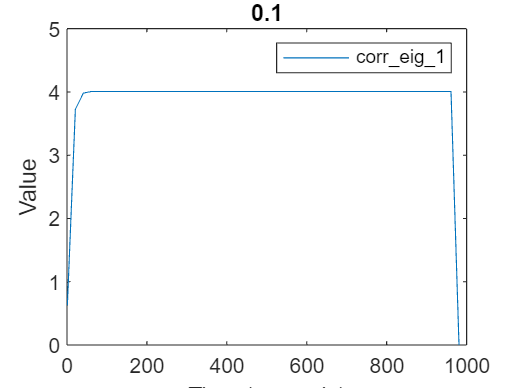

for i = 1:N-1
    % Filtering

    % Correction step
    % innovation
    r = y_meas(:,i) - C_async*xhat(:, i);
    % residual covariance
    S = C_async*P_pred*C_async' + R_async;
    % Kalman gain
    W = P_pred*C_async'/S;
    % update
    xhat(:, i) = xhat(:, i) + W*r; 
    yhat(i) = C_async*xhat(:,i);
    P_corr = P_pred - W*C_async*P_pred;
    % P(t|t)
    P_corr_eig(:,i) = eig(P_corr);
    

    % Prediction step
    xhat(:, i+1) = A_decor*xhat(:,i); + B_decor*u(:,i) + S_decor*inv(R_async)*y_meas(i);
    P_pred = A_decor*P_corr*A_decor' + Q_decor;
    % P(t+1|t)
    P_pred_eig(:,i+1) = eig(P_pred);
end

f = gcf;
plot([1:20:n_seconds], P_corr_eig(1,:));
hold off
ylabel("Value");
xlabel("Time (seconds)");
legend("corr\_eig\_1");
title(["Eigen values of decorrelated noise covariance Tc:" num2str(Tc*0.1)]);
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

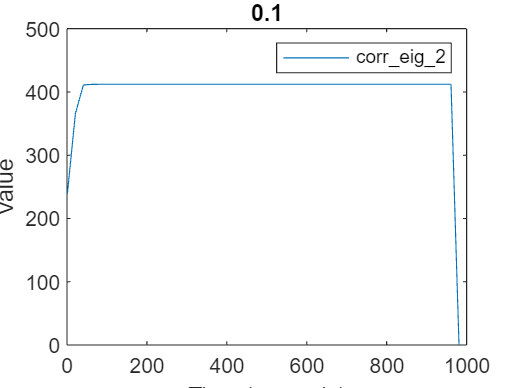

ind = ind + 1;
f = gcf;
plot([1:20:n_seconds], P_corr_eig(2,:));
hold off
ylabel("Value");
xlabel("Time (seconds)");
legend("corr\_eig\_2");
title(["Eigen values of decorrelated noise covariance  Tc:" num2str(Tc*0.1)]);
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

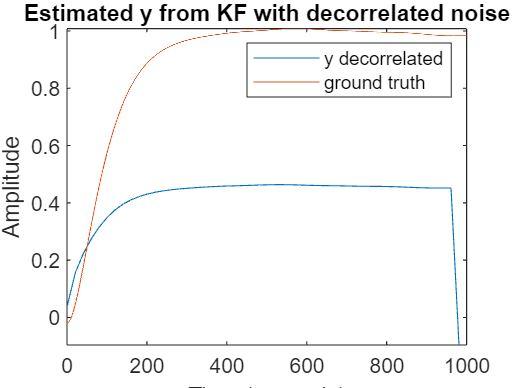

ind = ind + 1;
f = gcf;
plot([1:20:n_seconds], C_async*xhat);
hold on
plot([0.1:0.1:n_seconds], continuous_signal_y);
hold off
ylabel("Amplitude");
xlabel("Time (seconds)");
legend("y decorrelated", "ground truth")
title("Estimated y from KF with decorrelated noise");
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

ind = ind +1;
save("2final.mat")